## Problem 1 - Consensus

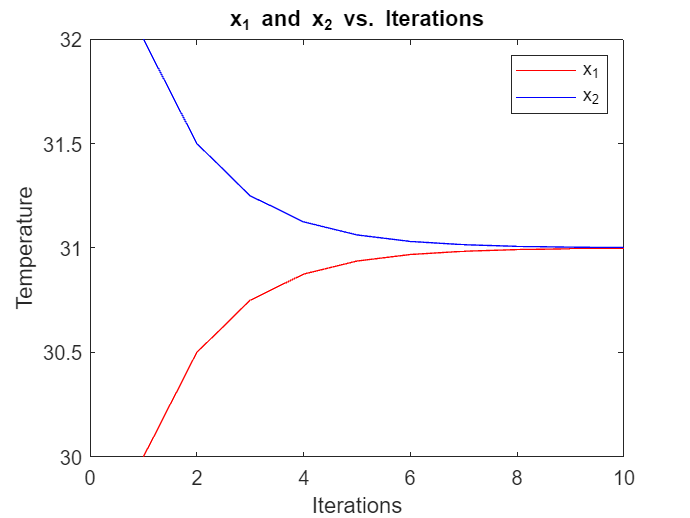

X = zeros(2,10); % initialize X array

X(:,1) = [30;32]; % set first coloumn of values in X

w = 0.25;
A = [1-w w; w 1-w]; % matrix relationship

for k = 1:size(X,2)-1 % iterate through all elements in X
    X(:,k+1) = A * X(:,k); % update X using the matrix relationship
end

plot(X(1,:),"r") % plot X_1
hold on
plot(X(2,:),"b") % plot X_2
legend(["x_1" "x_2"])
title("x_1 and x_2 vs. Iterations")
xlabel("Iterations")
ylabel("Temperature")
hold off

## Problem 2 - Statics

A = [cosd(60) -cosd(60); sind(60) sind(60)]; % matrix relationship

M = inv(A) * [0; -10] % compute member forces

M =    -5.7735
   -5.7735
